# Lab Template

This is an mlx (matlab live script) template for the labs. Live Script allows you to mix code with text. Try to structure you code with one cell/section per exercise and keep all functions in the ./functions directory and all images in the ./images directory.

## Setting up environment

Here we clear old variables and make sure that ./functions and ./images are in the path.

% use clear to avoid unknowingly being dependent on 
% variables in the workspace defined by other scripts
% or in the command window
clear;

%add ./functions and ./images folders to path
%addpath('./functions');
%addpath('./images');


## Load dataset

trainImagesFile = 'train-images.idx3-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';

XTrain = processMNISTimages(trainImagesFile);


Read MNIST image data...
Number of images in the dataset:  60000 ...



XTest = processMNISTimages(testImagesFile);


Read MNIST image data...
Number of images in the dataset:  10000 ...



YTest = processMNISTlabels(testLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


## Test 0, baseline

[encoderNet,decoderNet, latentDim, numEpochs, lr, momentum] = get_baseline_param();

[encoderNet0, decoderNet0] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 28.4724. Time taken for epoch = 128.6116s 
Epoch : 2 Test ELBO loss = 26.5353. Time taken for epoch = 136.3499s 


encoderNet =   dlnetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     Learnables: [6×3 table]
          State: [0×3 table]


decoderNet =   dlnetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
    Connections: [7×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]


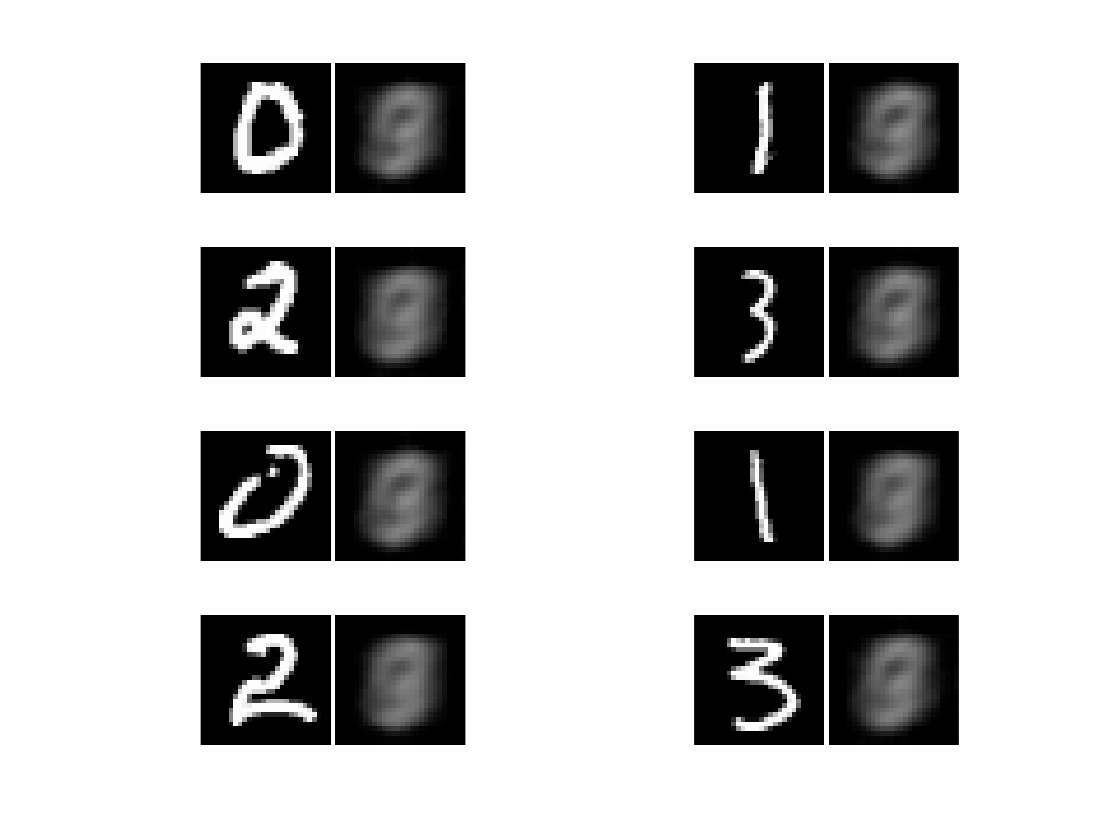

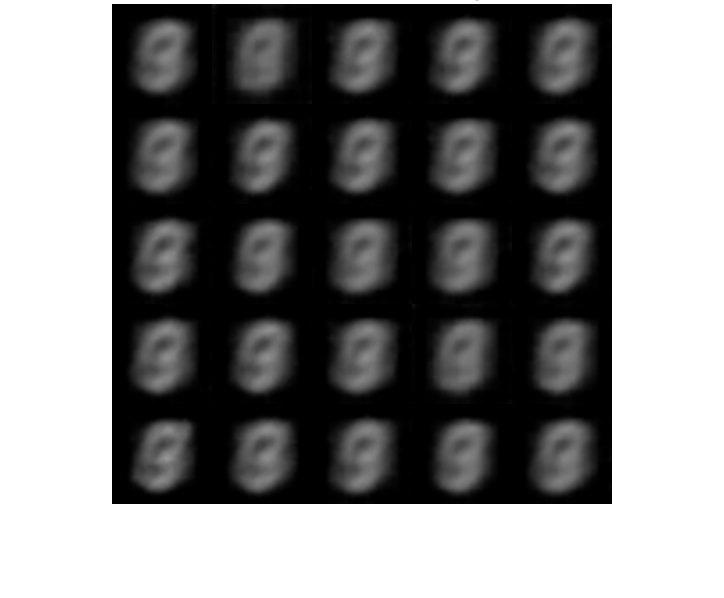


visualizeReconstruction(XTest, YTest, encoderNet0, decoderNet0)
%visualizeLatentSpace(XTest, YTest, encoderNet)
generate(decoderNet0, 2)

## Test 1

## Test 2

## Test 3

## Test 4

## Test 5

## Test 6

## Test 7

[encoderNet,decoderNet, latentDim, numEpochs, ~, momentum] = get_baseline_param();

encoderNet =   dlnetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     Learnables: [6×3 table]
          State: [0×3 table]


decoderNet =   dlnetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
    Connections: [7×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]



lr = 1e-2;

[encoderNet7, decoderNet7] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 27.4271. Time taken for epoch = 116.8727s 
Epoch : 2 Test ELBO loss = 26.9141. Time taken for epoch = 121.8481s 
Epoch : 3 Test ELBO loss = 26.649. Time taken for epoch = 116.5221s 


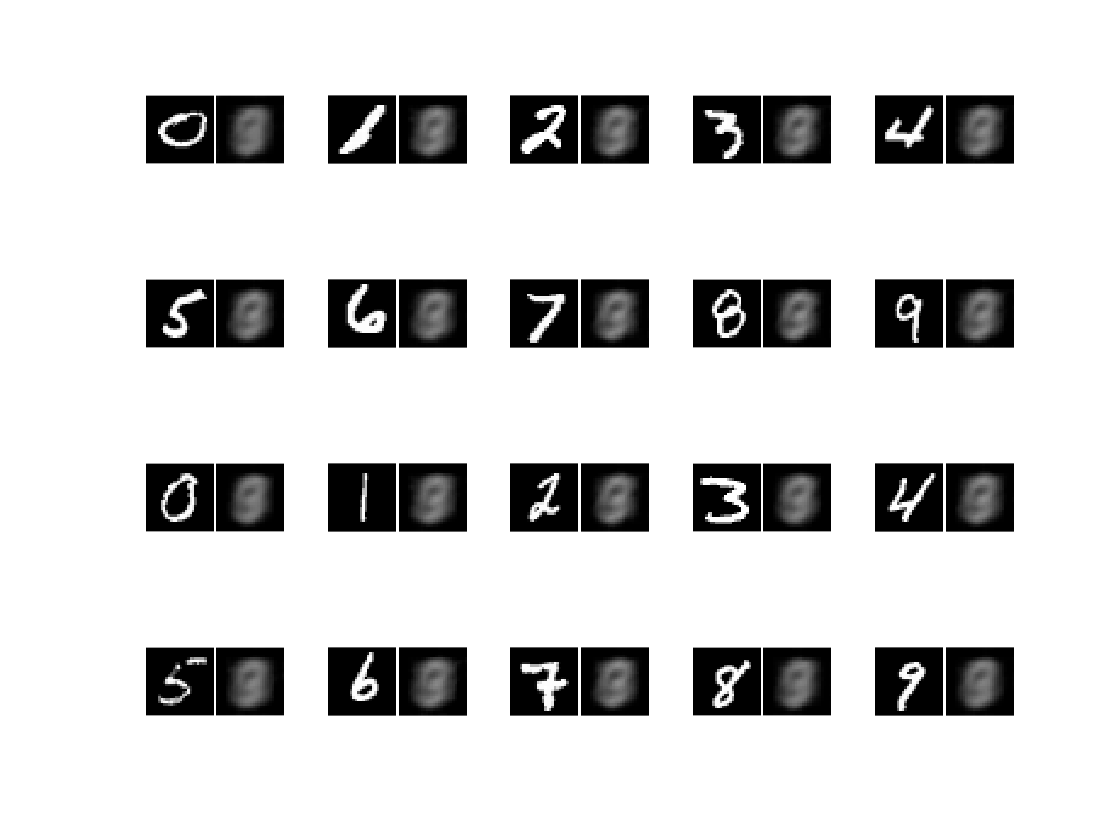


visualizeReconstruction(XTest, YTest, encoderNet7, decoderNet7)

generate(decoderNet7, latentDim)

Unrecognized function or variable 'latentDim'.

## Test 8

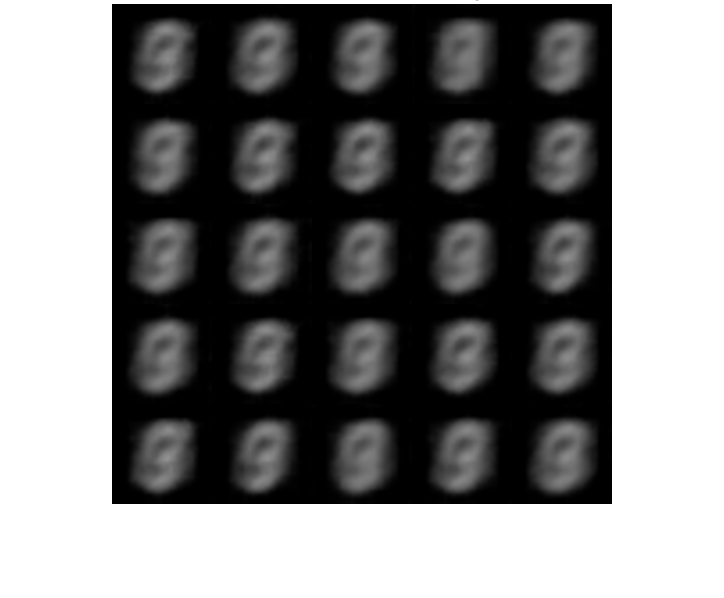

[encoderNet,decoderNet, latentDim, numEpochs, ~, momentum] = get_baseline_param();


lr = 1e-4;

[encoderNet8, decoderNet8] = run_training(numEpochs, lr, momentum, encoderNet, decoderNet, XTrain, XTest);

visualizeReconstruction(XTest, YTest, encoderNet8, decoderNet8)
generate(decoderNet8, latentDim)

## Test 9

## Test Final